## Partie I

#### Algorithme génétique

fichier = load("EteV35Nu10.txt");
Demande = fichier(:,2);
Peol = fichier(:,3);
Ppv = fichier(:,4);
Prix = fichier(:,5);

% données du problème 
Qh2ini = 10; %MWh
Ppacmax = 15; %MW
Pelecmin = 5; %MW
Pelecmax = 30; %MW 
Relec = 0.6;
Rpac = 0.8;
Celec = 1;
Cpac = -4;
Preste = Demande - Peol - Ppv;
Qh2jour = 0;
N=24;
QH2max = 30;

fobj = @(x) (Preste +x(1:N)')'*Prix + Celec*sum(x(1:N));

Aineq = [-eye(N) Pelecmin*eye(N) ; eye(N) -Pelecmax*eye(N) ; -ones(1,N)*Relec zeros(1,N)];

lb = [zeros(1,2*N)];
ub = [Pelecmax*ones(1,N) ones(1,N)];
intcon = N+1:2*N; % On précise que les On sont bien des variables entières

%Options 

Pop = 200;
options = optimoptions('ga');
options.PopulationSize = Pop;
options.ConstraintTolerance = 0.001;

% Après divers tests sur les valeurs des options, il s'avère que les
% valeurs par défaut fonctionnent très bien.

x0_On = randi(2,Pop,N)-1; %Création d'une liste d'entiers aléatoire entre 0 et 1
x0_P = (Pelecmin + rand(Pop,N)*(Pelecmax-Pelecmin)).*x0_On;
x0 = [x0_P,x0_On];
options.InitialPopulationMatrix = x0; %Ici, on force x0 à contenir des binaires pour les On. Sans cela, GA renvoie parfois des nombre réels entre 0 et 1. 
intcon = (N+1):N*2;
nbr_iter = 10;

Qh2jour = linspace(0,35,nbr_iter); % Après tests, GA se comporte identiquement une fois QH2jour de l'ordre de 35.  
x_ga = [];
fval_ga = [];

tic
for k = 1:nbr_iter
    Bineq = [zeros(2*N,1); -Qh2jour(k)];
    [x,fval, exitflag_gam] = ga(fobj,2*N,Aineq,Bineq,[],[],lb,ub,'',intcon,options);
    x_ga = [x_ga x(1:N)*x(N+1:2*N)'*Relec];
    fval_ga = [fval_ga -fval];
end

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.
Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less th

Toc = toc

Toc = 525.3093

#### Affichage des résultats pour GA

fprintf("Convergence pour GA")

Convergence pour GA

disp(exitflag_gam)

     1



fprintf("Pelec pour GA")

Pelec pour GA

disp(x(1:24))

  Columns 1 through 21

     0     0     0    30    30     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 22 through 24

     0     0     0



fprintf("Onelec")

Onelec

disp(x(25:48))

  Columns 1 through 21

     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 22 through 24

     0     0     0



fprintf("Somme gagnée sur la journée pour GA")

Somme gagnée sur la journée pour GA

disp(-fval)

  329.4811



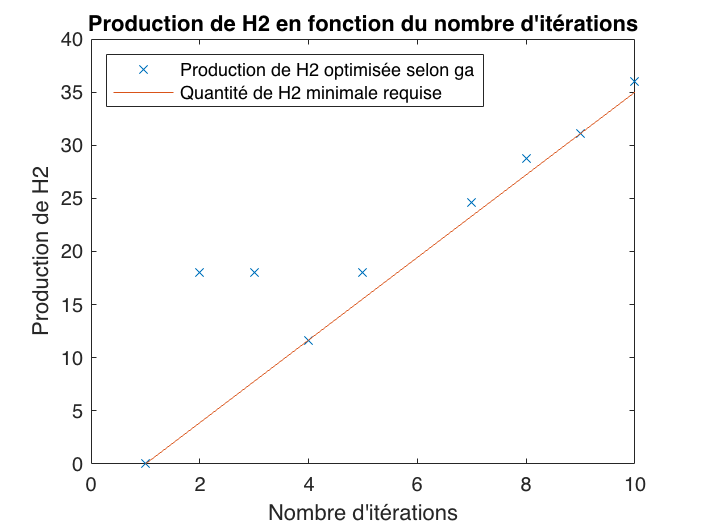



plot(linspace(1,nbr_iter,nbr_iter),x_ga,'x',linspace(1,nbr_iter,nbr_iter),Qh2jour)
title("Production de H2 en fonction du nombre d'itérations")
xlabel("Nombre d'itérations")
ylabel("Production de H2")
legend("Production de H2 optimisée selon ga",'Quantité de H2 minimale requise','Location','northwest')


%On observe que pour des valeurs de QH2 jour d'environ 25MW/jour, GA
%produit toujours la quantité minimale ce qui optimise par la même occasion
%le coût total. 

#### Algorithme "global search"

% On utilise le même processus que pour ga : 
x0=zeros(1,2*N);
x0(N+1:2*N) = randi(2,1,N)-1;
x0(1:N) = (Pelecmin + rand(1,N)*(Pelecmax-Pelecmin)).*x0(N+1:2*N);
X_gs = [];
fval_gs = [];
tic
for i = 1:nbr_iter
    Bineq = [zeros(2*N,1); -Qh2jour(i)];
    probleme = createOptimProblem('fmincon','x0',x0,'objective',fobj,'lb',lb,'ub',ub,'Aineq',Aineq,'bineq',Bineq);
    [x_gs,f_gs, exitflag_gs] = run(GlobalSearch,probleme); 
    for j = N+1:2*N
    if (x_gs(j) >0) && (x_gs(j)<1)
        x_gs(j)=1;% Sans cela, certaines valeurs des Onelec étaient réelles non entières. 
    end
    end
    X_gs = [X_gs x_gs(1:N)*x_gs(N+1:2*N)'*Relec];
    fval_gs = [fval_gs -f_gs];
end

GlobalSearch stopped because it analyzed all the trial points.

All 2 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

33 out of 35 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 33 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 38 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 45 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 47 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 48 local solver runs converged with a positive local solver exit flag.

GlobalSearch st

Toc2=toc

Toc2 = 23.7552

#### Affichage des résultats pour gs

fprintf("Convergence pour GS")

Convergence pour GS

disp(exitflag_gs)

     2



fprintf("Pelec pour GS")

Pelec pour GS

disp(X_gs)

    0.0000    3.8889    7.7778   11.6667   15.5556   19.4444   23.3333   27.2222   31.1111   35.0000



fprintf("Somme gagnée sur la journée pour GS")

Somme gagnée sur la journée pour GS

disp(fval_gs)

  693.3811  654.4921  615.6033  576.7144  537.8255  498.6237  458.8922  419.1607  379.4292  339.6977



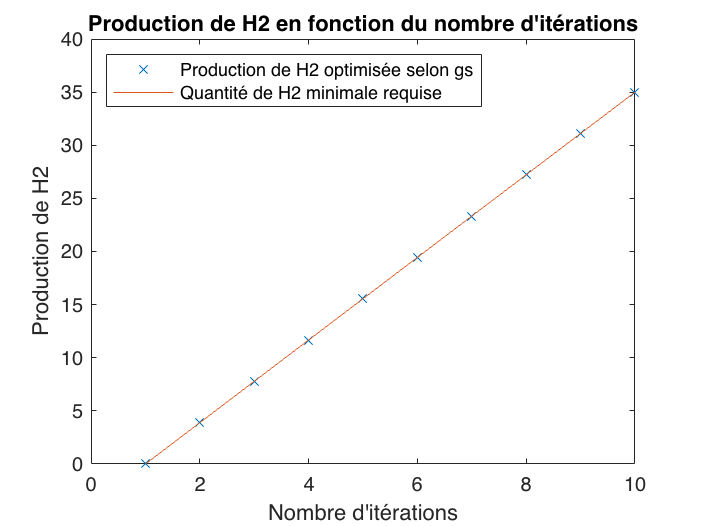



plot(linspace(1,nbr_iter,nbr_iter),X_gs,'x',linspace(1,nbr_iter,nbr_iter),Qh2jour)
title("Production de H2 en fonction du nombre d'itérations")
xlabel("Nombre d'itérations")
ylabel("Production de H2")
legend('Production de H2 optimisée selon gs',"Quantité de H2 minimale requise",'Location','northwest')

% On remarque que gs est plus performant que ga : il produit toujours la
% valeur requise. 


#### Comparaison du résultat des deux algorithmes : 

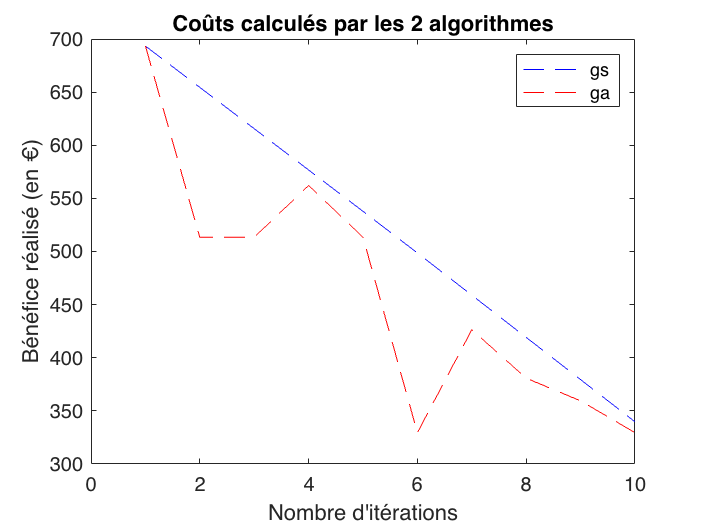

plot(linspace(1,nbr_iter,nbr_iter),fval_gs,'--b',linspace(1,nbr_iter,nbr_iter),fval_ga,'--r')
title('Coûts calculés par les 2 algorithmes')
xlabel("Nombre d'itérations")
ylabel('Bénéfice réalisé (en €)')
legend('gs','ga')


% GA est environ 3 fois plus lent que GS. De plus, GA semble trouver une
% solution moins optimisée au problème (moins bons bénéfices)

## Partie II

fichier2 = load("AutonV50Nu40.txt");
Demande2 = fichier2(:,2)';
Peol2 = fichier2(:,3)';
Ppv2 = fichier2(:,4)';
Prix2 = fichier2(:,5)';
Preste2 = Demande2 - Peol2 - Ppv2;
N=24;


Aeq2 = [];
beq2 = [];

Aineq2=[zeros(1,N) Rpac*ones(1,N)];
Bineq2=[QH2max];
lb2=[zeros(1,2*N)]';
ub2=[Pelecmax*ones(1,N) Ppacmax*ones(1,N)]';


fobj2 = @(x) [sum(x(N+1:2*N)); (Preste2-x(N+1:2*N)+x(1:N))*Prix2' + Cpac*sum(x(N+1:2*N)) + Celec*sum(x(1:N)) ];

nonlcon=[];
n_points = 10;
n_pop = 100;

lb2=[zeros(1,2*N)]';
ub2=[Pelecmax*ones(1,N) Ppacmax*ones(1,N)]';
options = optimoptions('gamultiobj');
options.PopulationSize = n_pop;
options.ParetoFraction = 0.10;


[x_gam,fval_gam,exitflag_gam] = gamultiobj(fobj2,2*N,Aineq2,Bineq2,Aeq2,beq2,lb,ub,nonlcon,options);

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


display(fval_gam)

fval_gam =    21.4679  538.0688
   16.9519  595.9721
   18.9375  555.9711
    1.8730  789.6857
   20.5332  555.1014
    5.6611  742.3188
   10.9515  650.5834
   15.6854  619.7375
   12.8341  645.7797
   14.2844  626.3177


display(x_gam)

x_gam =     0.2944    0.2398    0.7644    0.4697    1.3984    0.4201    0.8539    0.4884    0.2374    1.2011    0.6532    0.5154    0.5858    0.0864    0.5686    0.1805    0.1191    0.1889    0.1766    0.1494    0.4854    0.1583    0.2854    0.3285    0.8573    0.9999    0.9874    0.9514    0.9357    0.4975    0.9277    0.7448    0.6993    0.9952    0.9999    0.9599    0.8671    0.9959    0.9989    0.9997    0.8526    0.9989    0.9987    0.8512    0.7688    0.6464    0.9928    0.9408
    0.2570    0.1856    0.6568    0.3679    0.8156    0.3254    0.6600    0.3150    0.0895    1.4719    0.6130    0.4977    0.5449    0.0854    0.6727    0.2018    0.1346    0.2027    0.1663    0.1403    0.4683    0.1366    0.3627    0.1775    0.6420    0.6095    0.7292    0.9039    0.8678    0.4398    0.8617    0.4238    0.4596    0.8201    0.7352    0.8093    0.8633    0.9242    0.9567    0.6813    0.6183    0.9416    0.6614    0.5712    0.5466    0.4794    0.7541    0.6520
    0.0942    0.0891    0.6064

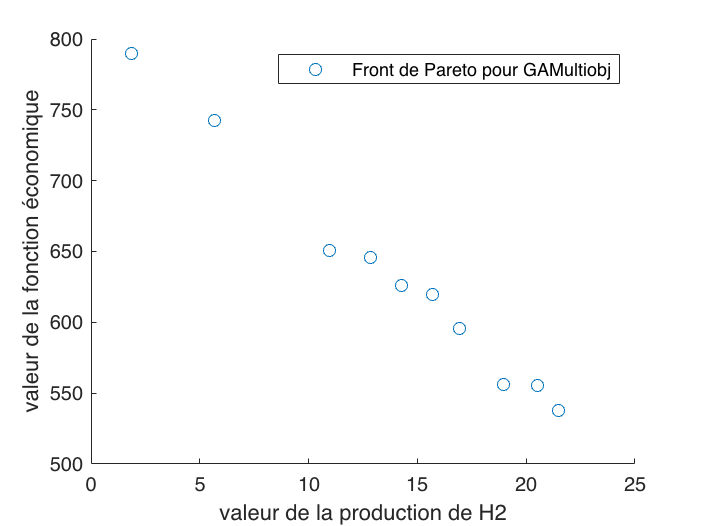


figure
scatter(fval_gam(:,1),fval_gam(:,2))
xlabel('valeur de la production de H2')
ylabel('valeur de la fonction économique')
legend('Front de Pareto pour GAMultiobj')


options = optimoptions('paretosearch');
options.ParetoSetSize = n_points;
options.MinPollFraction = 1;
On = randi(2,n_points,N) - 1;
Init = [On.*rand(n_points,N)*QH2max/Relec/24 , (1 - On).*rand(n_points,N)*QH2max*Rpac/24];
options.InitialPoints = Init;


[x5,fval5,exitflag5,output5,residuals5] = paretosearch(fobj2,2*N,Aineq2,Bineq2,Aeq2,beq2,lb,ub,nonlcon,options)


Pareto set found that satisfies the constraints. 

Optimization completed because the relative change in the volume of the Pareto set 
is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within 
'options.ConstraintTolerance'.



x5 =     1.4008    0.9236         0         0         0    1.4118         0    0.5077         0         0    1.6561         0         0         0    0.2629    0.4847         0    1.9201         0         0         0         0         0    0.1492         0         0         0         0         0         0    0.3757         0    0.5902    0.6352         0    0.1229    0.3873    0.6706         0         0    0.7894         0    0.1841    0.6640         0    0.3754    0.1366         0
    1.4008    0.9236         0         0         0    1.4118         0    0.5077         0         0    1.6561         0         0         0    0.2629    0.4847         0    1.9201         0         0         0         0         0    0.1492         0         0         0         0    0.3674         0    0.3757         0    0.5902    0.6352         0    0.1229    0.3873    0.6706         0         0    0.7894         0    0.1841    0.6640         0    0.3754    0.1366         0
         0         0    1.8692   

fval5 =     4.9314  754.8708
    5.2988  750.6451
    9.3366  679.2471
   11.3462  650.0961
    6.2660  735.8886
    4.7273  797.8211
    7.7183  710.2675
    8.7045  697.3605
    3.2713  821.8058
   10.7700  658.8866


exitflag5 = 1

output5 = struct with fields:
         iterations: 10
          funccount: 2112
             volume: 1.0491e+03
    averagedistance: 0.0761
             spread: 0.9885
      maxconstraint: 0
            message: 'Pareto set found that satisfies the constraints. ↵↵Optimization completed because the relative change in the volume of the Pareto set ↵is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within ↵'options.ConstraintTolerance'.'
           rngstate: [1×1 struct]


residuals5 = struct with fields:
         lower: [10×48 double]
         upper: [10×48 double]
       ineqlin: [10×1 double]
         eqlin: [10×0 double]
    ineqnonlin: [10×0 double]


display(fval5)

fval5 =     4.9314  754.8708
    5.2988  750.6451
    9.3366  679.2471
   11.3462  650.0961
    6.2660  735.8886
    4.7273  797.8211
    7.7183  710.2675
    8.7045  697.3605
    3.2713  821.8058
   10.7700  658.8866


display(x5)

x5 =     1.4008    0.9236         0         0         0    1.4118         0    0.5077         0         0    1.6561         0         0         0    0.2629    0.4847         0    1.9201         0         0         0         0         0    0.1492         0         0         0         0         0         0    0.3757         0    0.5902    0.6352         0    0.1229    0.3873    0.6706         0         0    0.7894         0    0.1841    0.6640         0    0.3754    0.1366         0
    1.4008    0.9236         0         0         0    1.4118         0    0.5077         0         0    1.6561         0         0         0    0.2629    0.4847         0    1.9201         0         0         0         0         0    0.1492         0         0         0         0    0.3674         0    0.3757         0    0.5902    0.6352         0    0.1229    0.3873    0.6706         0         0    0.7894         0    0.1841    0.6640         0    0.3754    0.1366         0
         0         0    1.8692   

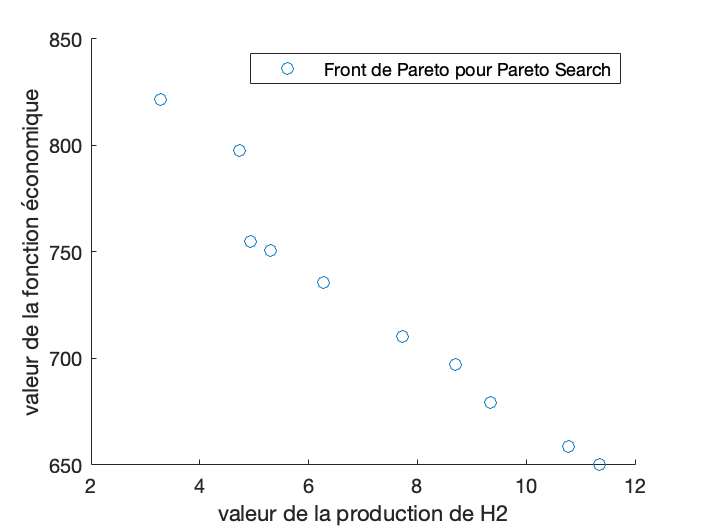


figure
scatter(fval5(:,1),fval5(:,2))
xlabel('valeur de la production de H2')
ylabel('valeur de la fonction économique')
legend('Front de Pareto pour Pareto Search')

#### Comparaison des 2 algorithmes : 

Pareto search est meilleur en coût et surtout moins "anarchique" que GAMultiobj. 

Même si GAMultiobj est plus rapide, on préfèrera ParetoSearch. 